# GUIA CODI FEM

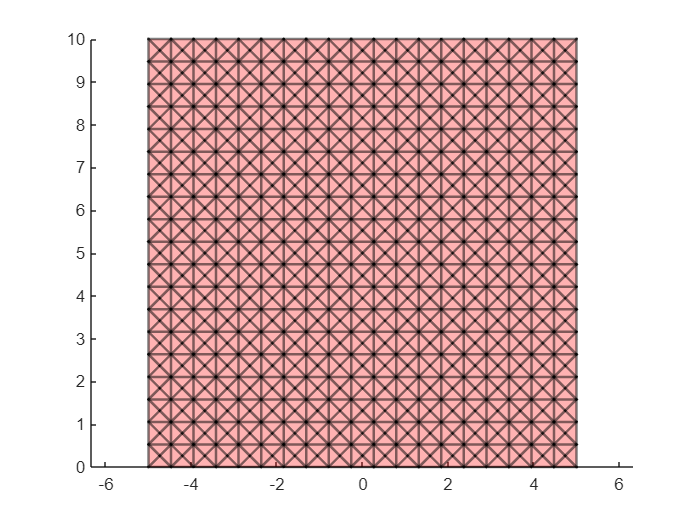

%% CREACIÓ DE LA MALLA
clear;
close all;

% Generate coordinates
x1 = linspace(-5,5,20);
x2 = linspace(0,10,20);

% Create the grid
[xv,yv] = meshgrid(x1,x2);

% Triangulate the mesh to obtain coordinates and connectivities
[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

s.coord  = V(:,1:2);
s.connec = F;
bgMesh = Mesh.create(s);

figure()
bgMesh.plot()

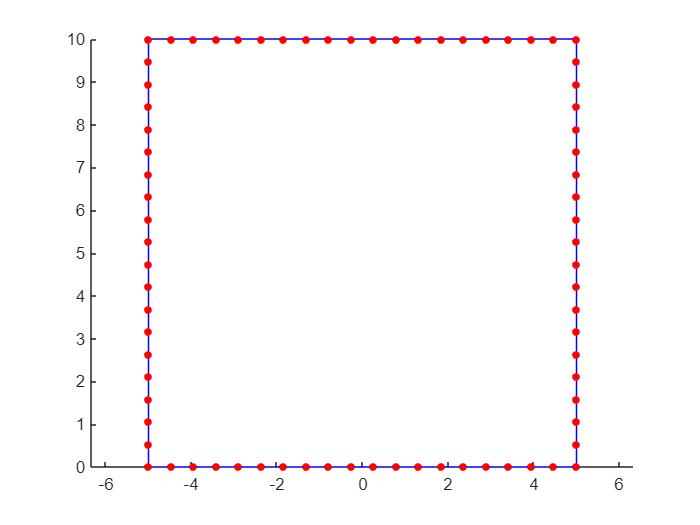

% Creacio boundary mesh
boundaryMesh  = bgMesh.createBoundaryMesh();  

% En crea 4 meshes corresponents als boundaries de la background mesh (original d'adalt)
figure
boundaryMesh{1}.mesh.plot()
hold on
boundaryMesh{2}.mesh.plot()
boundaryMesh{3}.mesh.plot()
boundaryMesh{4}.mesh.plot()

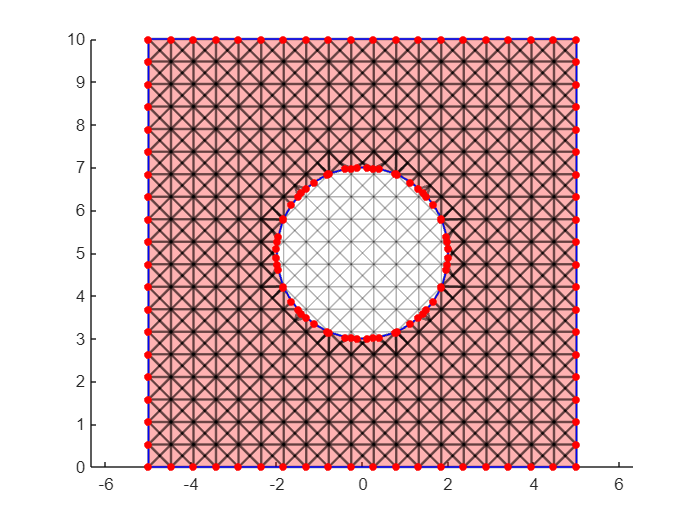

% LevelSetFunction pel Forat
sLS.type        = 'CircleInclusion';
sLS.xCoorCenter = 0;    %coordenada y del centre
sLS.yCoorCenter = 5;  %coordenada y del centre
sLS.radius      = 2;
g               = GeometricalFunction(sLS);
lsFun           = g.computeLevelSetFunction(bgMesh);
levelSet        = lsFun.fValues;

%Ara s'intersecciona la LevelSet function amb la background mesh
sUm.backgroundMesh = bgMesh;          % Defineix la background mesh
sUm.boundaryMesh   = bgMesh.createBoundaryMesh();   %calcula el boundary mesh corresponent
uMesh = UnfittedMesh(sUm);   % background+boundary
uMesh.compute(levelSet);     % inclusio radi

figure
uMesh.plot()

% Guardem aquesta malla en un obj
obj.radius=sLS.radius;
obj.mesh = uMesh.createInnerMesh();
obj.boundaryMesh = obj.mesh.createBoundaryMesh();
[obj.boundaryMeshJoined, obj.localGlobalConnecBd] = obj.mesh.createSingleBoundaryMesh();

% Resolem Elastic problem

fem = PhysicalProblem.create(obj);
